# Face Detection using PCA, MDA, K-NN and Bayes Decision Theory - Pose.mat

## Loading Dataset

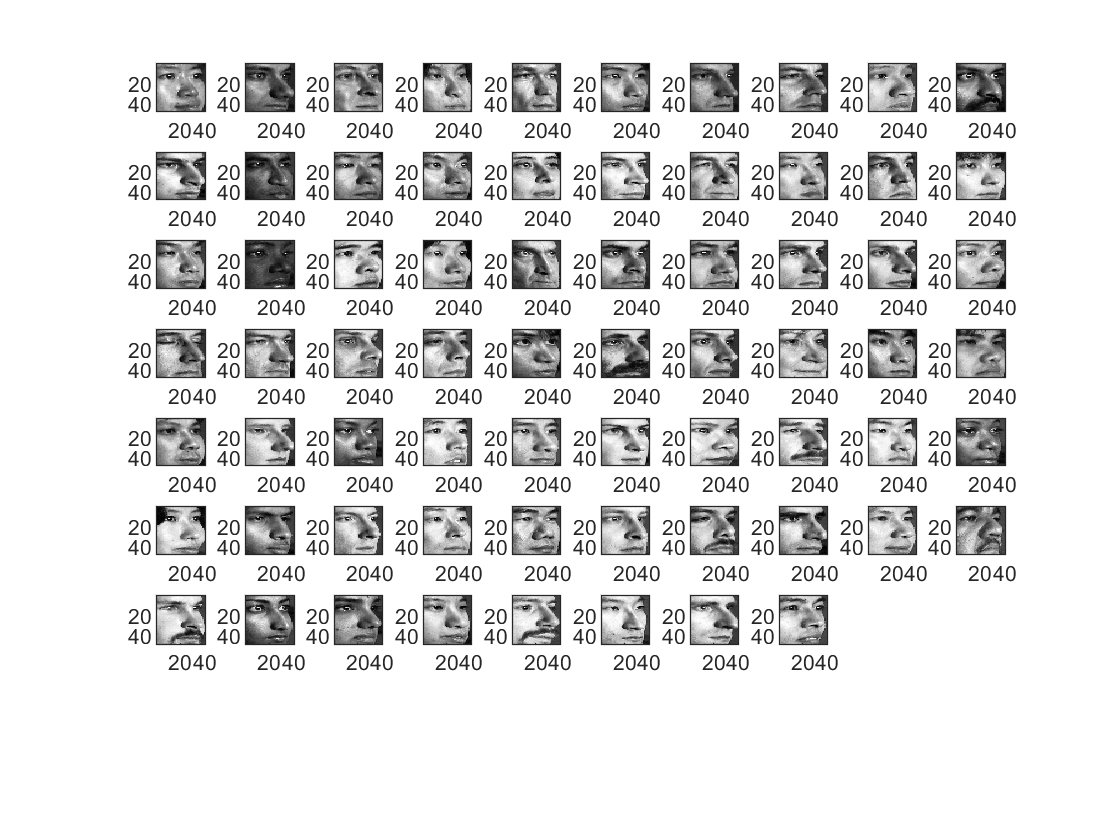


data = load('pose.mat');
pose = data.pose;
% Each image is 48x40 pixel image, there are 13 images for each subject and 68 subjects
figure, clf;
colormap 'gray';
%display the 1st image of each subject
for i=1:68
    subplot(8,10,i);
    imagesc(pose(:,:,1,i)); 
end

## Prepare Train and Test datasets

Using the 1st 10 images for training pupose and testing on remaining 3 for each subject.

trn_sz = 10;
[d1, d2] = deal(size(pose,1), size(pose,2));
X=zeros(trn_sz*size(pose,4), d1*d2);
Y_trn=[];
for i=1:size(pose,4)
    for j=1:trn_sz
        tmp = pose(:,:,j,i);
        X((i-1)*trn_sz + j,:) = tmp(:)';
    end
    Y_trn = [Y_trn; ones(trn_sz,1)*i];
end
Y_lbl=[];
for i=1:size(pose,4)
    for j=trn_sz+1:size(pose,3)
        tmp = pose(:,:,j,i);
        X_tst((i-1)*(size(pose,3) - trn_sz) + j - trn_sz,:) = tmp(:)';
        Y_lbl = [Y_lbl;i];
    end
end

## Start Multiple Discriminant Analysis

mu_tot = mean(X); % Calculate total mean of all classes
mu_i = zeros(size(pose,4),d1*d2);
Sb = zeros(d1*d2); 
Sw = zeros(d1*d2);
for i=1:size(pose,4)
    mu_i(i,:) = mean(X((i-1)*trn_sz+1:i*trn_sz,:)); %Calculate mean for each class
    %Calculate Scatter between class Sb and within class Sw
    Sb = Sb + trn_sz*(mu_i(i) - mu_tot)*(mu_i(i) - mu_tot)';
    Sw = Sw + (X((i-1)*trn_sz+1:i*trn_sz,:) - ones(trn_sz,1)*mu_i(i,:))'*(X((i-1)*trn_sz+1:i*trn_sz,:) - ones(trn_sz,1)*mu_i(i,:));
end

[eig_vec , eig_val] = eig(Sb,Sw);
[eig_s, isort] = sort(diag(eig_val),"descend");
eig_vec = eig_vec(:,isort);
W = eig_vec(:,1:size(pose,4)-1); %Taking the 1st 67 Eigenvectors for MDA as there are 68 classes

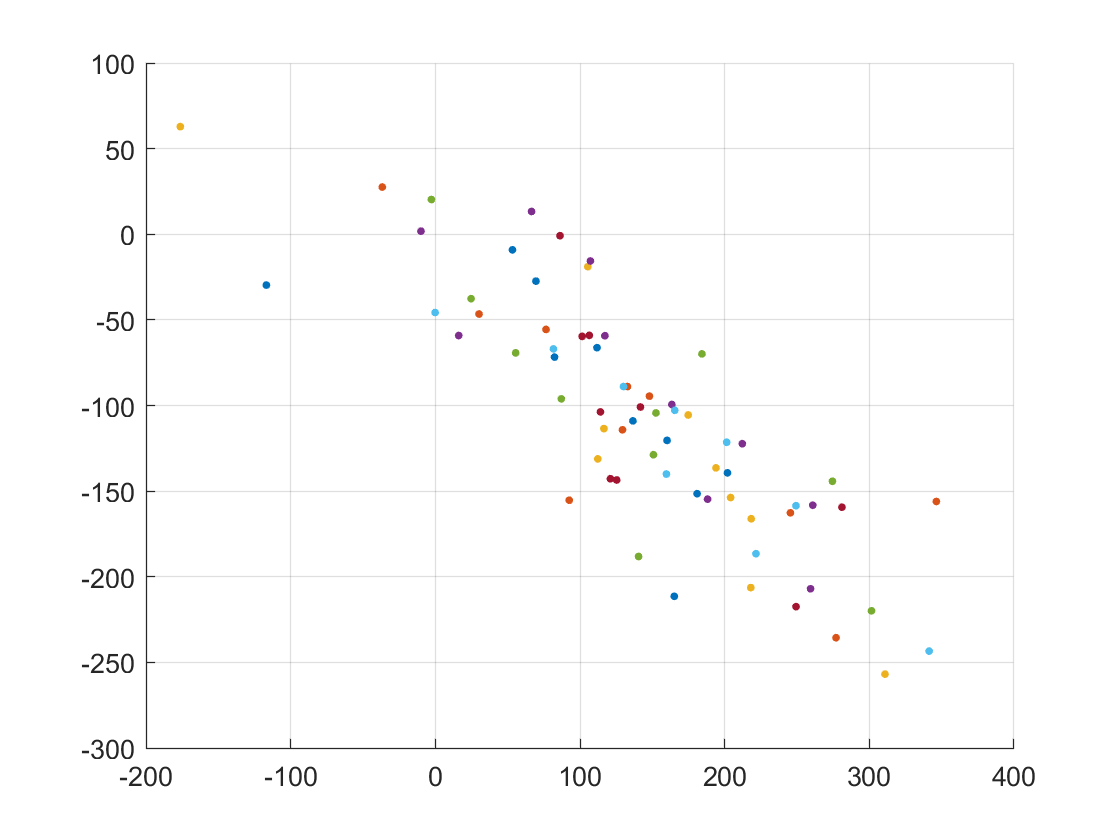

% Map the training and testing set to the 67 reduced dimension that have maximum
% separation between classes factored by the variance
Y = X*W;
Y_tst = X_tst*W;
%Plot the 68 classes to visually inspect their separation and variability
figure, clf; grid; hold on;
for i=1:size(pose,4)
    plot3(Y((i-1)*trn_sz+1:i*trn_sz,1),Y((i-1)*trn_sz+1:i*trn_sz,2),Y((i-1)*trn_sz+1:i*trn_sz,3),'.','MarkerSize',10);
 %   plot3(Y_tst(i*3-2:i*3,1),Y_tst(i*3-2:i*3,2),Y_tst(i*3-2:i*3,3),'+','MarkerSize',10);
 %   plot3(Y(68*trn_sz+1,1),Y(68*trn_sz+1,2),Y(68*trn_sz+1,3),'+','MarkerSize',10);
end
hold off

On visual inspection, the data looks pretty clustered and separated for each each 68 classes. On zooming in, it's discovered all 10 training points almost coincide in 3-D (taking 1st 3 dimensions after MDA). Hence it looks to be an easy candidate for K-NN classification

## Run K-NN classification on MDA outcome

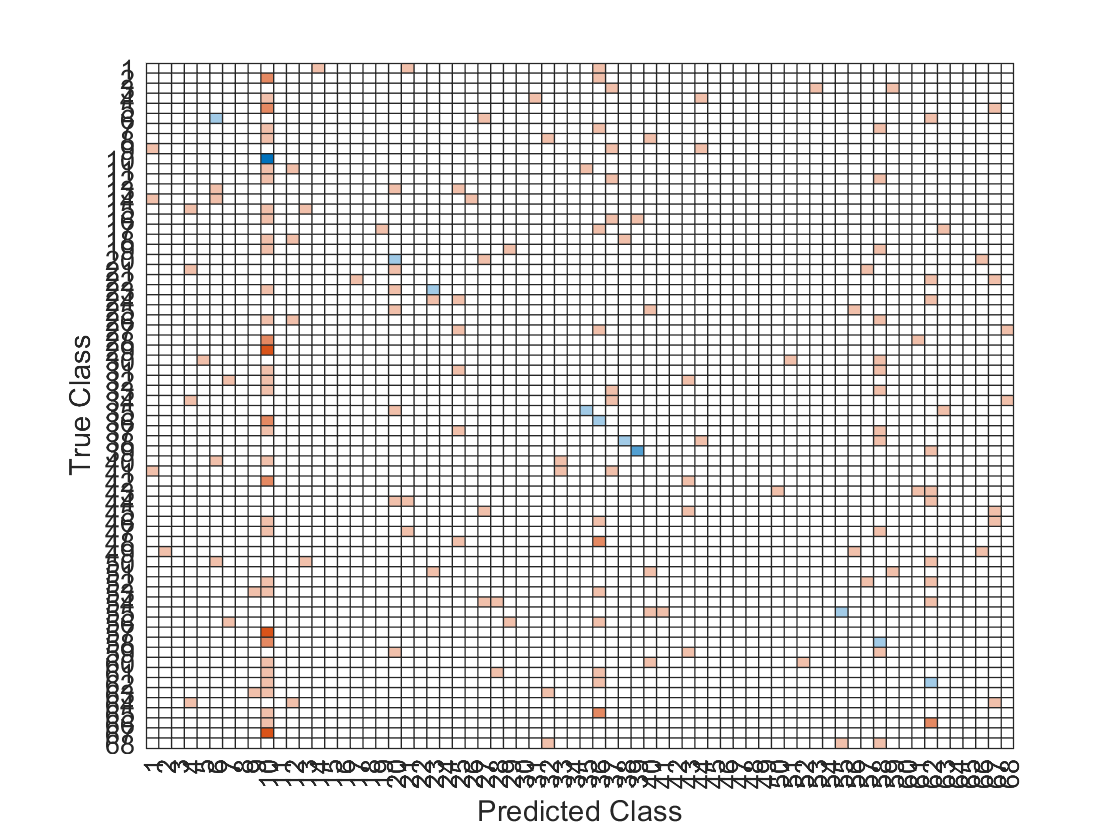

k_face = fitcknn(Y,Y_trn,"NumNeighbors",5,"Distance","euclidean");
label = predict(k_face,Y_tst);

C = confusionmat(Y_lbl,label);
cm = confusionchart(C);

correct=0;
for i=1:size(pose,4)
    correct = correct + cm.NormalizedValues(i,i);
end
accuracy = correct/((size(pose,3)-trn_sz)*size(pose,4))

accuracy = 0.0686

The classification performed very poorly although the training set was well clustered together (6% accuracy). As the number of training sets are very less compared to the dimensions, the classification didn't work as expected. In next attempt we'll try to reduce dimensionality with PCA and then conduct the MDA.

## Run Principle Component Analysis

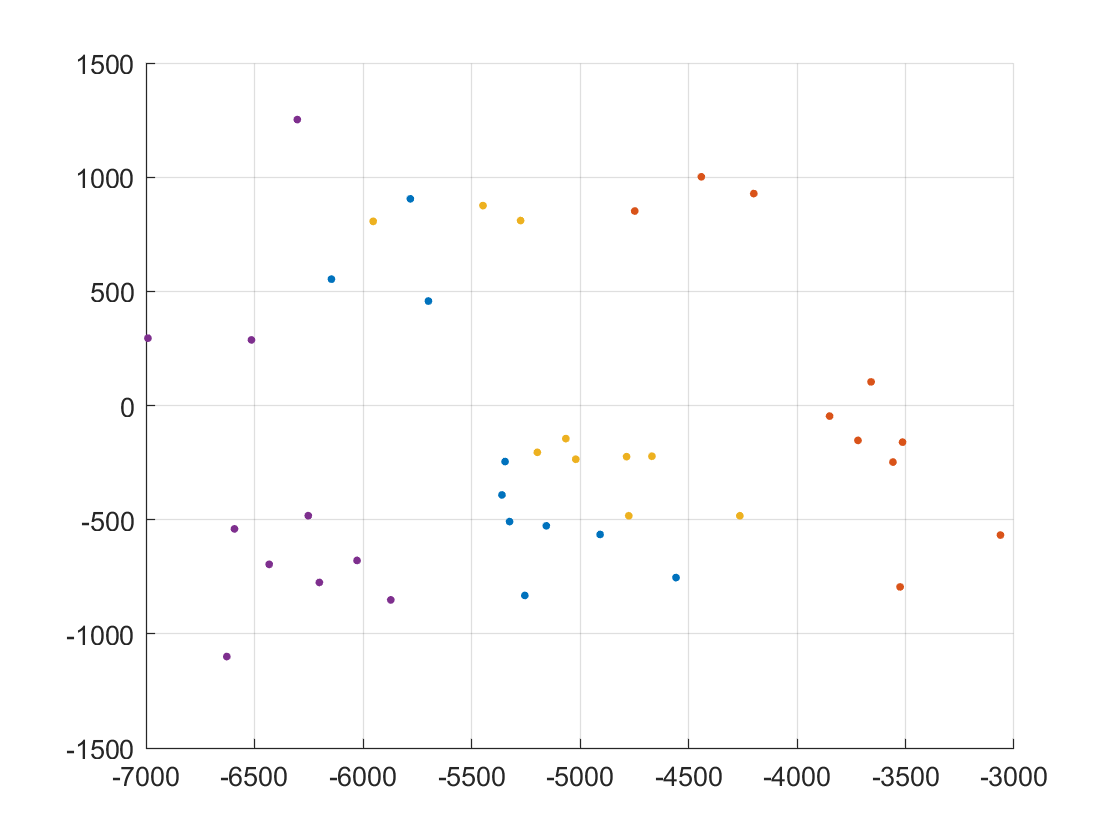

nPCA=67; % Taking top 67 dimenions as the MDA will have max (c-1)=68 dimensions.
[U, Sigma, V] = svd(X','econ');
Y_pca = X*U(:,1:nPCA);
figure; hold on; grid;
% for i=1:size(pose,4)
for i=1:4
    plot3(Y_pca((i-1)*trn_sz+1:i*trn_sz,1),Y_pca((i-1)*trn_sz+1:i*trn_sz,2),Y_pca((i-1)*trn_sz+1:i*trn_sz,3),'.',"MarkerSize",10);
end
hold off

Plotting the training points for 1st 4 classes to visually inspect the their variability in 3-D. On closer look the data looks pretty clustered for each separate class. Next further conduct MDA on the reduced dimension received from PCA.

mu_totpca = mean(Y_pca);
mu_ipca = zeros(size(pose,4),nPCA);
Sb_pca = zeros(nPCA); 
Sw_pca = zeros(nPCA);
for i=1:size(pose,4)
    mu_ipca(i,:) = mean(Y_pca((i-1)*trn_sz+1:i*trn_sz,:));
    Sb_pca = Sb_pca + trn_sz*(mu_ipca(i) - mu_totpca)*(mu_ipca(i) - mu_totpca)';
    Sw_pca = Sw_pca + (Y_pca((i-1)*trn_sz+1:i*trn_sz,:) - ones(trn_sz,1)*mu_ipca(i,:))'*(Y_pca((i-1)*trn_sz+1:i*trn_sz,:) - ones(trn_sz,1)*mu_ipca(i,:));
end

[eig_vecp , eig_valp] = eig(Sb_pca,Sw_pca);
[eig_sp, isortp] = sort(diag(eig_valp),"descend");
eig_vecp = eig_vecp(:,isortp);
W_pca = eig_vecp(:,1:size(pose,4)-1);

Mapping the training and testing data to reduced dimension over the PCA reduced dimension.

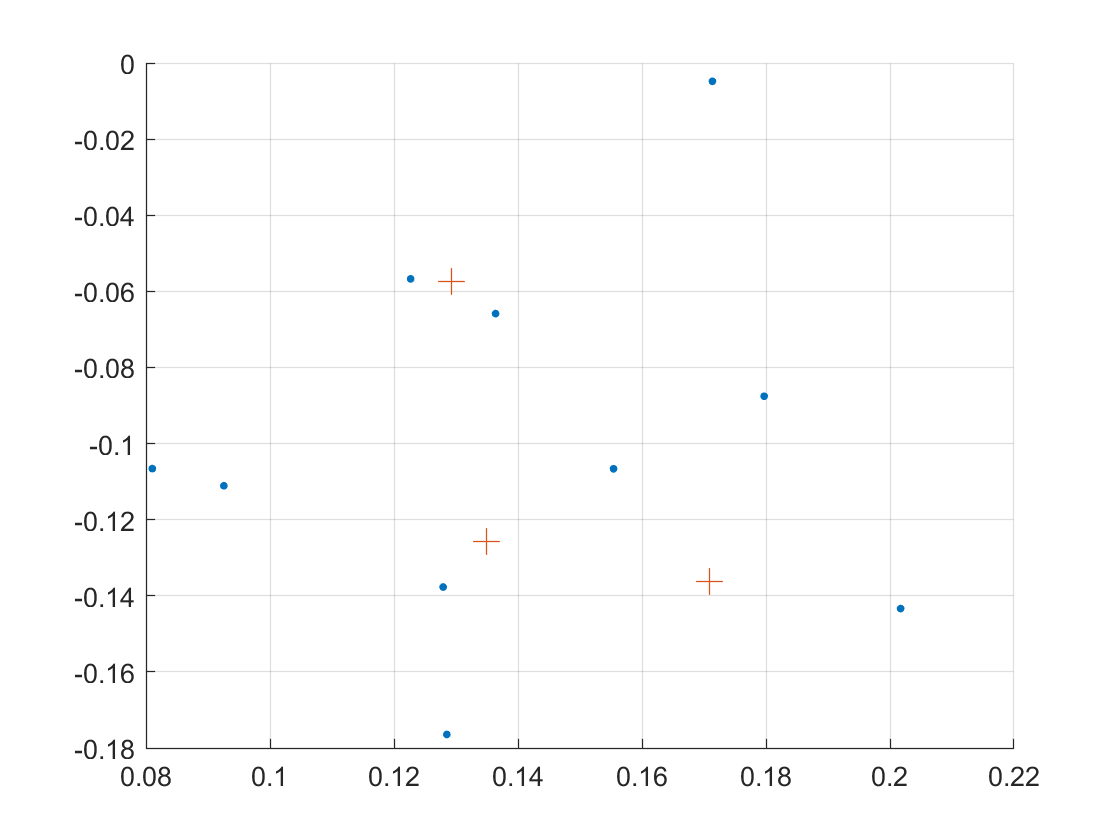

Y_pm = Y_pca*W_pca;
Y_tmp = X_tst*U(:,1:nPCA);
Y_tstpm = Y_tmp*W_pca;
figure, clf; grid; hold on;
for i=1:1
    plot3(Y_pm((i-1)*trn_sz+1:i*trn_sz,1),Y_pm((i-1)*trn_sz+1:i*trn_sz,2),Y_pm((i-1)*trn_sz+1:i*trn_sz,3),'.','MarkerSize',10);
    plot3(Y_tstpm((i-1)*3+1:i*3,1),Y_tstpm((i-1)*3+1:i*3,2),Y_tstpm((i-1)*3+1:i*3,3),'+','MarkerSize',10);
end
hold off

The Training points look pretty close to the testing points in 3-D. So K-NN classification should work well here.

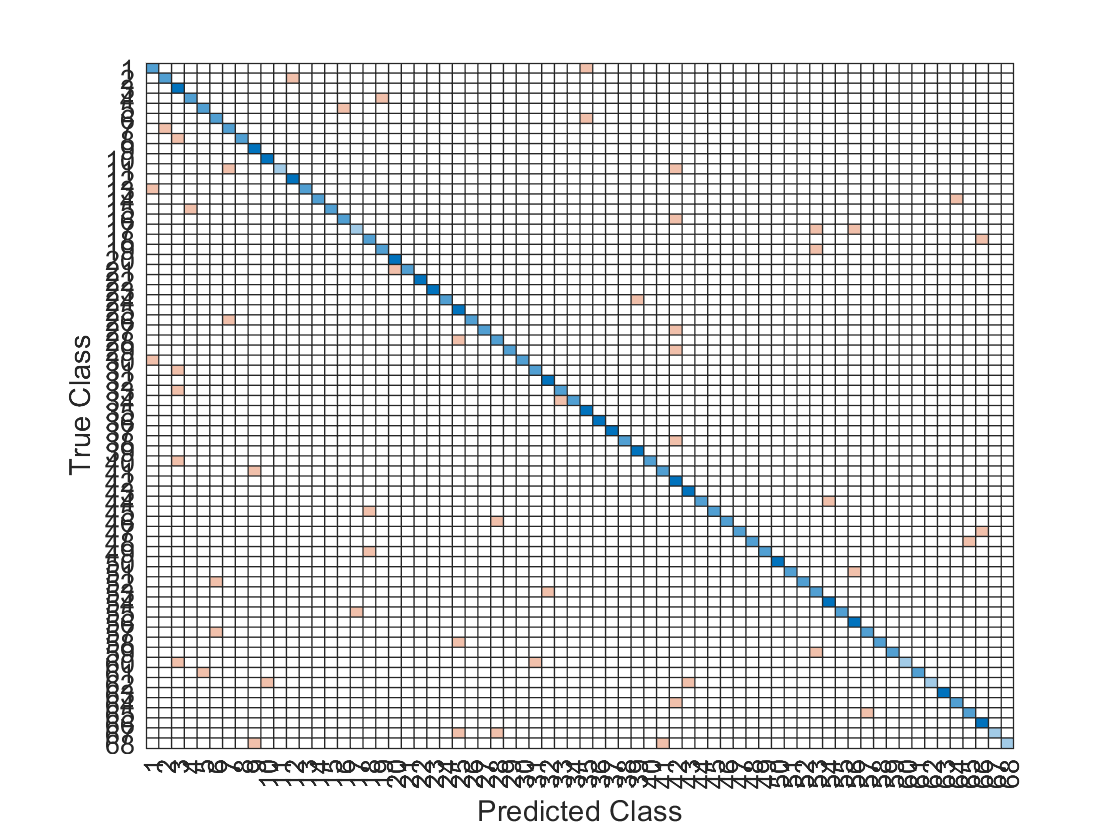

k_facep = fitcknn(Y_pm,Y_trn,"NumNeighbors",3,"Distance","euclidean");
label = predict(k_facep,Y_tstpm);
C = confusionmat(Y_lbl,label);
cm = confusionchart(C);

correct = 0;
for i=1:size(pose,4)
    correct = correct + cm.NormalizedValues(i,i);
end
accuracy = correct/((size(pose,3)-trn_sz)*size(pose,4))

accuracy = 0.7353

The accuracy score has improved to a great extent to 73.5%. 

Next we'll select 1st 3 subjects only and attempt to classify the corresponding test images using Bayesian decision theory.

## Bayesian Classification over PCA and MDA reduced dimensions

for i=1:3
    for j=1:3
        norm_pca(i,j) = norm(mean(Y_pm((i-1)*trn_sz+1:i*trn_sz,:)) - mean(Y_pm((j-1)*trn_sz+1:j*trn_sz,:)));
    end
end
norm_pca

norm_pca =          0    0.6195    0.4876
    0.6195         0    0.4715
    0.4876    0.4715         0


The norm between the class means are well spaced considering the scale. However, taking all 67 dimensions, the covariance matrix generated is nearly singular. As a result the Bayesian classification has to be conducted over further reduced dimensions - say 5.

W_pcab = eig_vecp(:,1:size(pose,4)-63); %This will pick the 1st 5 Eigenvectors only from the MDA computation
Y_pmb = Y_pca*W_pcab;
Y_tmpb = X_tst*U(:,1:nPCA);
Y_tstpmb = Y_tmp*W_pcab;

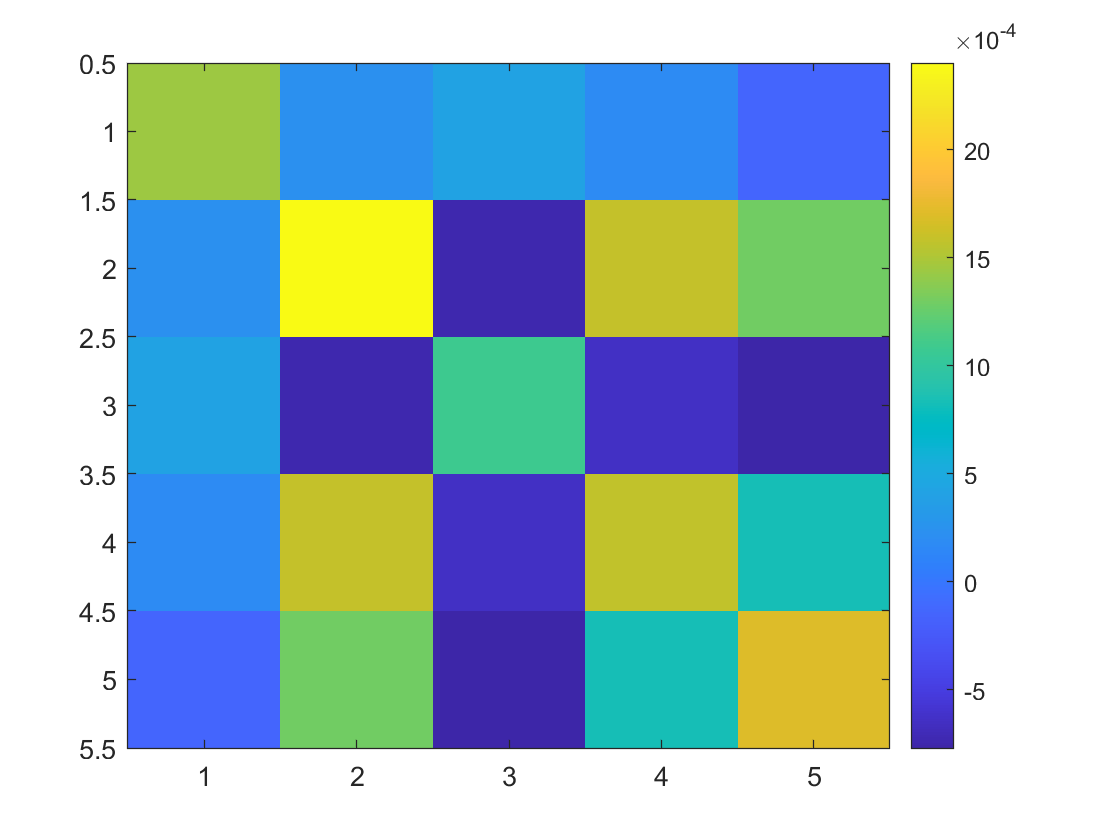

Y_pmc =[]; S_pmc=[]; iS_pmc = []; S_pmcd = [];
%Calculate the Covariance Matrix between the 5 dimensions, and its inverse
%and determinant
for i=1:size(pose,4)
    Y_pmc = [Y_pmc;Y_pmb((i-1)*trn_sz+1:i*trn_sz,:) - ones(trn_sz,1)*mean(Y_pmb((i-1)*trn_sz+1:i*trn_sz,:))];
    S_pmc = [S_pmc;cov(Y_pmc((i-1)*trn_sz+1:i*trn_sz,:))];
    iS_pmc = [iS_pmc; inv(S_pmc((i-1)*5+1:i*5,:))];
    S_pmcd(i) = (det(S_pmc((i-1)*5+1:i*5,:)));
end
%Define the Bayesion decision functions for each of 3 subjects 
f1 = @(x)((2*pi)^(-nPCA*0.5))*(1/(S_pmcd(1,1)^0.5))*exp((-0.5)*((x-mean(Y_pmb(1:10,:)))*iS_pmc(1:5,:)*(x-mean(Y_pmb(1:10,:)))'));
f2 = @(x)((2*pi)^(-nPCA*0.5))*(1/(S_pmcd(1,2)^0.5))*exp((-0.5)*((x-mean(Y_pmb(11:20,:)))*iS_pmc(6:10,:)*(x-mean(Y_pmb(11:20,:)))'));
f3 = @(x)((2*pi)^(-nPCA*0.5))*(1/(S_pmcd(1,3)^0.5))*exp((-0.5)*((x-mean(Y_pmb(21:30,:)))*iS_pmc(11:15,:)*(x-mean(Y_pmb(21:30,:)))'));
figure; clf;
imagesc(S_pmc(1:5,:)); colorbar;

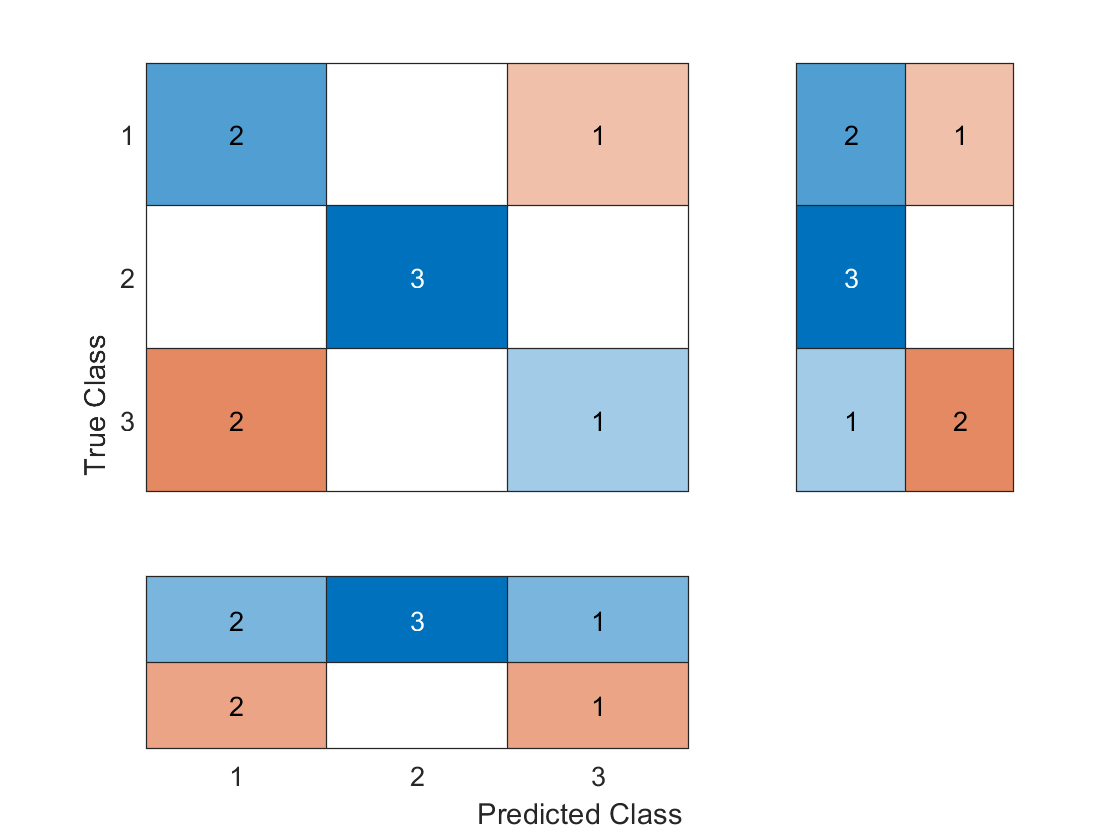

label = [];
for i=1:3*(size(Y_tstpmb,1)/68)
    p1 = f1(Y_tstpmb(i,:)); 
    p2 = f2(Y_tstpmb(i,:));
    p3 = f3(Y_tstpmb(i,:));
    p4 = f4(Y_tstpmb(i,:));
    label(i,:) = [p1,p2,p3,p4];
end
[ps, ipsort] = sort(label,2,"descend","MissingPlacement","last");
C = confusionmat(Y_lbl(1:9,1),ipsort(:,1));
cm = confusionchart(C,"RowSummary","absolute","ColumnSummary","absolute");

Accuracy = 6/9 = **66.6%**